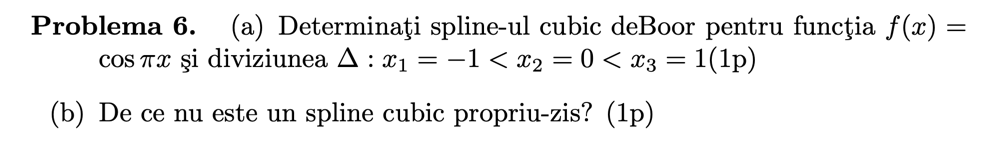

## Solutie

nodes=[-1 0 1]

nodes =     -1     0     1


f=@(x) cos(pi*x);
values=f(nodes)

values =     -1     1    -1


Trebuie sa gasim un spline cubic deBoor intr-o diviziune formata de n=3 puncte. Asta inseamna ca va trebui sa gasim 2 polinoame cubice ($p_i \left(x\right)=c_{i,0} +c_{i,1} \;x+c_{i,2} \;x^2 +c_{i,3} \;x^3$).

Problema spline-urilor este insuficienta ecuatiilor. Ele incearca sa egaleze nodurile de fixate cu valorile corespondente ($\left.p_i \left(x_i \right)=f_i ,\;i=0\ldotp \ldotp n-1,\mathrm{rezultand}\;\mathrm{in}\;n-1\;\mathrm{ecuatii}\right)$, dar si pentru nodurile din capatul drept (deci $p_i \left(x_{i+1} \right)=f_i ,i=0\ldotp \ldotp n-1$, rezultand tot in $n-1$ ecuatii). Pe langa acestea, ele si sa egaleze derivatele de ordinul 1 si 2 in punctele de jonctiune (${p_i }^{\prime } \left(x_{i+1} \right)={p_{i+1} }^{\prime } \left(x_{i+1} \right),$$\left.{{p_i }^{\prime } }^{\prime } \left(x_{i+1} \right)={{p_{i+1} }^{\prime } }^{\prime } \left(x_{i+1} \right),i=0\ldotp \ldotp \ldotp n-2,\mathrm{rezultand}\;\mathrm{in}\;2n-4\;\mathrm{ecuatii}\right)$

In total am obtinut $2n-2+2n-4=4n-6$ ecuatii, insa avem $4n-4$ necunoscute (4 pentru fiecare $p_{i=0\ldotp \ldotp n-1}$). De aceasta putem defini mai multe tipuri de spline sa completeze acele conditii.

Spline-ul cubic deBoor are proprietatea ca:

${{{p_1 }^{\prime } }^{\prime } }^{\prime } \left(x_2 \right)={{{p_2 }^{\prime } }^{\prime } }^{\prime } \left(x_2 \right)$ si ${{{p_{n-1} }^{\prime } }^{\prime } }^{\prime } \left(x_{n-1} \right)={{{p_{n-2} }^{\prime } }^{\prime } }^{\prime } \left(x_{n-1} \right)$

Deoarece $n=3$, problema este ca spline-ul deBoor in acest context adauga o singura informatie  $\mathrm{deoarece}\;n-1=2\;\mathrm{si}\;n-2=1$, deci a adaugat aceeasi ecuatie de 2 ori, deci vom avea un sistem subdeterminat (cu $4n-5$ ecuatii si $4n-4$ necunoscute), deci toate valorile vor depinde de o variabila. Scriem ecuatiile reiesite din spline-ul cubic deBoor:

syms p0 [1 4];
syms p1 [1 4];

eq01=p0(1) + p0(2)*nodes(1) + p0(3)*nodes(1)^2 + p0(4)*nodes(1)^3 == values(1), ...
    eq02=p1(1) + p1(2)*nodes(2) + p1(3)*nodes(2)^2 + p1(4)*nodes(2)^3 == values(2)

$$eq01 = p_{01}-p_{02}+p_{03}-p_{04}=-1$$

$$eq02 = p_{11}=1$$

eq11=p0(1) + p0(2)*nodes(2) + p0(3)*nodes(2)^2 + p0(4)*nodes(2)^3 == values(2), ...
    eq12=p1(1) + p1(2)*nodes(3) + p1(3)*nodes(3)^2 + p1(4)*nodes(3)^3 == values(3)

$$eq11 = p_{01}=1$$

$$eq12 = p_{11}+p_{12}+p_{13}+p_{14}=-1$$

eq2=p0(2) + 2*p0(3)*nodes(2) + 3*p0(4)*nodes(2)^2 == p1(2) + 2*p1(3)*nodes(2) + 3*p1(4)*nodes(2)^2

$$eq2 = p_{02}=p_{12}$$

eq3=2*p0(3) + 6*p0(4)*nodes(2) == 2*p1(3) + 6*p1(4)*nodes(2)

$$eq3 = 2\,p_{03}=2\,p_{13}$$

eq4=6*p0(4)==6*p1(4) % ecuatia adaugata de spline-ul deBoor

$$eq4 = 6\,p_{04}=6\,p_{14}$$

[p01,p02,p03,p04,p11,p12,p13]=solve([eq01 eq02 eq11 eq12 eq2 eq3 eq4], [p0(1),p0(2),p0(3),p0(4),p1(1),p1(2),p1(3)])

$$p01 = 1$$

$$p02 = -p_{14}$$

$$p03 = -2$$

$$p04 = p_{14}$$

$$p11 = 1$$

$$p12 = -p_{14}$$

$$p13 = -2$$

syms alfa;
c=[np01 subs(np02, p1(4), alfa) np03 subs(np04, p1(4), alfa); np11 subs(np12, p1(4), alfa) np13 alfa]

$$c = \left(\begin{array}{cccc} 1 & -\mathrm{alfa} & -2 & \mathrm{alfa}\\ 1 & -\mathrm{alfa} & -2 & \mathrm{alfa} \end{array}\right)$$

Observam ca variabilele rezultat depind de $p_{14}$.

function S=evalsplinecubic(x,nodes,values,c)
    S=zeros(1, length(x));
    for i=1:length(x)
         if x(i)==nodes(end)
             S(i)=values(end);
         else
             poz=find(nodes>x(i),1)-1;
             X=x(i);
             S(i)=c(poz,1)+X*(c(poz,2)+X*(c(poz,3)+X*c(poz,4)));
         end
    end
end

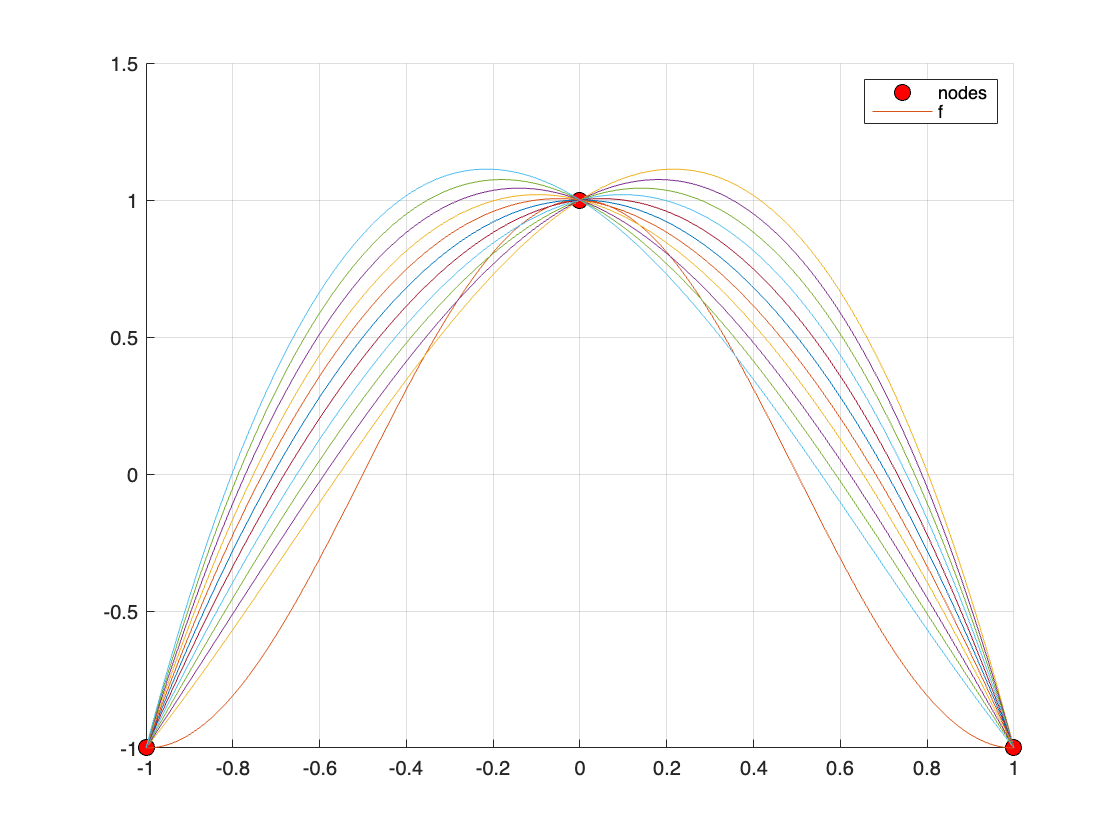

x=linspace(-1, 1, 1000);
clf; hold on; grid on;
plot(nodes, values, 'ok', 'markerfacecolor', 'r', 'markersize', 8)
plot(x, f(x))
for i=-1:0.2:1
    cn=double(subs(c,alfa,i));
    S=evalsplinecubic(x,nodes,values,cn);
    plot(x, S);
end
legend("nodes", "f")

Deci se observa ca nu obtinem doar o solutie, ci o infinitate, deci din acest motiv, nu este un spline cubic propriu zis.